**Progetto in ambito oncologico**

***Descrizione***:

Il progetto si propone di sviluppare un sistema integrato per la raccolta, archiviazione e analisi dei dati clinici relativi ai pazienti affetti da tumore al fegato. Questo sistema consente di gestire e valutare informazioni cruciali come diagnosi, trattamenti e esiti dei pazienti, e ha come obiettivi principali:

-  *Gestione dei dati*: fornire un metodo strutturato per inserire e aggiornare i dati dei pazienti, inclusi dettagli su diagnosi, tipo di tumore, trattamenti ricevuti e risultati dei follow-up.

- *Monitoraggio e analisi:* analizzare i dati raccolti per monitorare l'andamento della malattia e valutare l'efficacia dei trattamenti. Questo permette di identificare pattern e tendenze significative nel progresso della malattia e nella risposta ai trattamenti.

- *Supporto alla decisione clinica:* offrire strumenti per visualizzare e interpretare i dati attraverso grafici, aiutando i medici a prendere decisioni informate riguardo alle strategie terapeutiche e al follow-up dei pazienti.

- *Prevenzione e intervento: *Rilevare eventuali anomalie o deviazioni nei dati dei pazienti che possano richiedere un'attenzione medica tempestiva, migliorando la capacità di rispondere rapidamente a cambiamenti nella condizione dei pazienti.

***Creazione database***

Il database è già stato precedentemente creato su MySQL Workbench ed è il seguente: 

***Connessione al Database***

% Questo script gestisce l'interazione con il database per inserire e visualizzare pazienti.
dsn = 'MySQL_LiverCancer'; % dsn: Definisce il nome del Data Source Name (DSN), che è un alias per accedere al database MySQL tramite ODBC.

disp("E' necessario aver installato MySQL per utilizzare il programma"); % visualizza il messaggio desiderato

% Richiedi l'inserimento di username e password
username = input('Inserisci il tuo username MySQL: ', 's');
password = input('Inserisci la tua password MySQL: ', 's');

% Controlla se l'utente ha dimenticato di inserire username o password
if isempty(username) || isempty(password) %  isempty verifica se la variabile è vuota. In questo caso, viene controllato se username o password sono vuoti.
    disp('Attenzione: devi inserire sia il nome utente che la password!');
    return;  % Interrompe l'esecuzione se username o password non sono stati inseriti
end   

% Crea una connessione al database
conn = database(dsn, username, password); % È una funzione di MATLAB che apre una connessione a un database specificato

% Verifica se la connessione è riuscita
 if isopen(conn) % Questa funzione verifica se la connessione al database (conn) è aperta e valida. Se la connessione è riuscita, il risultato è vero (true), quindi il blocco di codice all'interno dell'if verrà eseguito.
    disp('Connessione al database riuscita.');
    randomInsertion(conn); % Chiama la funzione per l'inserimento dei dati
    menu(conn); % Questa sezione presenta un menu per interagire con il database
 else % Se la connessione non è valida o non è riuscita, il blocco else verrà eseguito.
    disp('Connessione al database fallita.');
    disp(conn.Message);  % Mostra il messaggio di errore
    return;
end

***Progettazione Concettuale***

La progettazione concettuale si concentra sulla definizione delle entità principali del dominio di interesse e delle loro interrelazioni. 

Per il nostro progetto in ambito oncologico, sono state identificate due entità chiave:

- **Patients**: è un'entità che rappresenta le informazioni di base sui pazienti, tra i quali il codice identificativo, nome, cognome, età, genere e codice fiscale che risultano essere attributi.

- **Diagnoses**: è un'entità che rappresenta le informazioni sulle diagnosi associate ai pazienti e comprende i seguenti attributi, la data della diagnosi, il tipo di diagnosi e lo stadio del tumore e ovviamente il codice identificativo della diagnosi e del paziente.

- **Treatments**:  rappresenta l'entità che descrive i trattamenti somministrati ai pazienti. Ogni paziente, nel contesto del trattamento della patologia, può essere sottoposto a una specifica terapia o intervento medico al quale è collegato un esito, che deve essere registrato e tracciato nel sistema.

- **Outcomes**:  è un'entità che rappresenta lo stato clinico del paziente a seguito del trattamento per il tumore al fegato e durante i follow-up periodici. 

La relazione tra queste entità è a due a due di tipo uno-a-uno, ogni paziente ha una sola e unica diagnosi, un solo trattmento e un unico esito.

***Progettazione Logica***

Durante la fase di progettazione logica, il modello concettuale è stato trasformato in un modello logico adatto per l'implementazione su un database management system. In questa fase abbiamo definito le strutture delle tabelle e le chiavi:

**Tabella Patients**: Progettata per includere un identificativo unico per ogni paziente, oltre ai campi per nome, cognome, età, sesso e codice fiscale.

**Tabella Diagnoses**: comprende un identificativo unico per ogni diagnosi e per ogni paziente, quest'ultimo è una chiave esterna che fa riferimento alla chiave primaria contenuta nella tabella *Patients, *la data e il tipo di diagnosi.

**Tabella Treatments**: descrive le informazioni relative ai trattamenti ricevuti dai pazienti. Contiene vari attributi che sono stati definiti per memorizzare in modo dettagliato i dati relativi al trattamento del tumore al fegato. Anche in questo caso il paziente è identificato da una chiave esterna che fa riferimento alla chiave primaria contenuta nella tabella *Patients.*

**Tabella Outcomes**: contiene una serie di attributi che memorizzano informazioni dettagliate relative agli esiti della malattia o della terapia seguita dai pazienti. Così come nelle precedenti tabelle anche qui l'ID del paziente è una chiave esterna che fa riferimento alla chiave primaria contenuta nella tabella *Patients.*

***Progettazione Fisica***

Questa fase finale ha comportato l'implementazione fisica del database nel sistema di gestione scelto, MySQL Workbench. Le attività principali includono:

- **Creazione fisica delle tabelle**: Utilizzando comandi SQL per definire la struttura di ciascuna tabella secondo il modello logico.

- **Implementazione della CLI:** attraverso delle funzioni specifiche vi è la presenza di una Command-Line Interface che permette all'utente di aggiornare il database e ottenere informazioni.

**Diagramma ER**

ll diagramma Entità-Relazione (ER) riflette la struttura logica:

- **Patients** è l'entità principale che contiene informazioni sui pazienti..

- **Diagnoses**, **Treatments**, e **Outcomes** sono collegate alla tabella **Patients** tramite la chiave esterna **PatientID**.

- Le relazioni tra **Patients** e le altre tabelle sono di tipo "Uno a Uno", indicato dalla cardinalità "1:1". Questo significa che per ogni record in **Patients**, ci sarà esattamente un record associato nelle tabelle **Diagnoses**, **Treatments** e **Outcomes**.

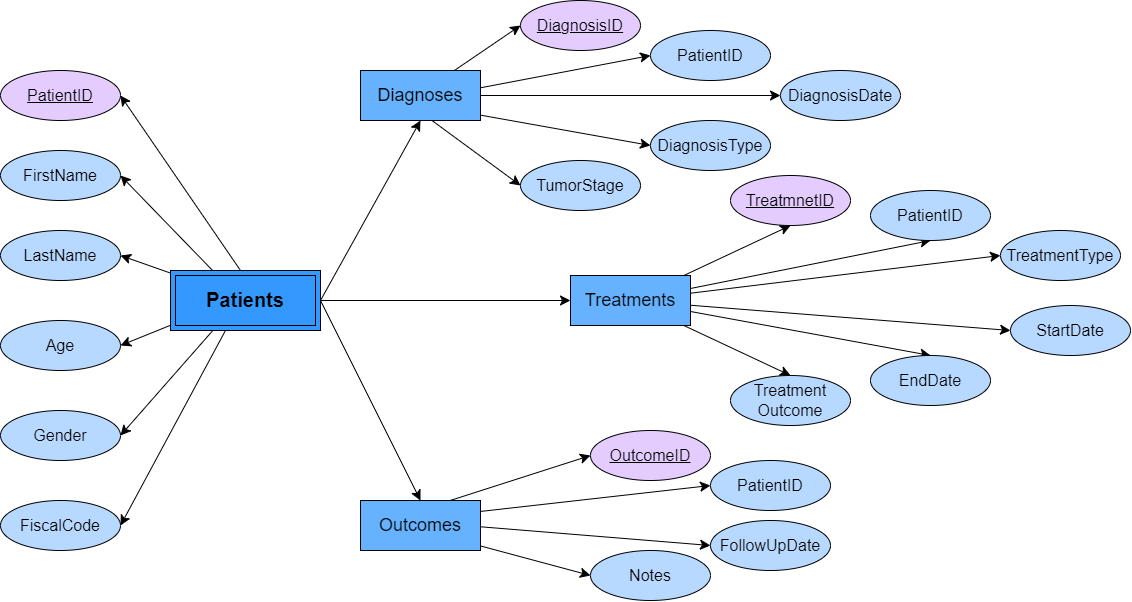

Funzione per gestire il menu

function menu(conn) 
    % Presenta un menu all'utente per scegliere l'operazione da eseguire e definisce la funzione menu che prende un parametro di input conn, che rappresenta la connessione al database.
    while true % Il ciclo while true significa che il menu continuerà a essere visualizzato e permetterà di eseguire operazioni finché l'utente non seleziona l'opzione per uscire (opzione 99).
        fprintf("Seleziona un'opzione: \n\n"); % fprintf è una funzione che stampa un testo sulla console. È simile a disp, ma più flessibile
        fprintf('1. Inserisci un paziente \n\n'); 
        fprintf('2. Visualizza informazioni su un paziente \n\n');
        fprintf('3. Visualizza grafici \n\n')
        fprintf('99. Esci \n\n'); 
        
        % Richiedi l'opzione all'utente
        option = input('Inserisci il numero dell''opzione scelta: ', 's'); % Assegna il valore inserito dall'utente alla variabile option, input è una funzione che richiede all'utente di inserire un valore da tastiera.
        
        % Verifica l'opzione e esegui il codice corrispondente
        switch option %switch valuta il valore della variabile option e confronta tale valore con i diversi case definiti.
            case '1' %Se option è uguale a '1', viene eseguito il blocco corrispondente.
                % Inserisci paziente
                Add_Patient(conn); %Chiama la funzione per aggiungere un paziente specifico. Anche qui viene passato conn per accedere al database.
                
            case '2'
                % Visualizza info paziente
                Info_patient(conn); %Chiama la funzione per visualizzare le informazioni su un paziente specifico. Anche qui viene passato conn per accedere al database.
            case '3'
                % Visualizza grafici
                Graphs_Menu(conn); %Chiama la funzione per visualizzare i grafici.
                
            case '99'
                % Esci dal programma
                disp('Uscita dal programma.');
                break; %Termina il ciclo while in cui si trova il blocco switch, uscendo così dal menu.
                
            otherwise %Questo blocco viene eseguito se option non corrisponde a nessuno dei valori precedenti.
                % Opzione non valida
                disp('Opzione non valida. Per favore, seleziona un numero tra 1 e 99.');
        end
    end
    close(conn); % questa funzione chiude la connessione al database.
    disp('Connessione al database chiusa.');
end


`Inserimento dati`

function randomInsertion(conn)
    % Definisci i nomi e i cognomi per i pazienti
    firstNames = {'Luca', 'Giulia', 'Marco', 'Anna', 'Francesco', 'Laura', 'Alessandro', 'Sara', 'Matteo', 'Chiara'}; %firstNames: È un array di stringhe che contiene 10 nomi propri comuni in Italia, utilizzati per generare i nomi dei pazienti.
    lastNames = {'Rossi', 'Bianchi', 'Verdi', 'Russo', 'Ferrari', 'Esposito', 'Colombo', 'Romano', 'Ricci', 'Marino'}; %È un array di stringhe che contiene 10 cognomi comuni, usati per generare casualmente i cognomi dei pazienti.
    genderOptions = {'M', 'F'}; %È un array che contiene le opzioni di genere, "M" per maschio e "F" per femmina.

    % Array per tenere traccia dei codici fiscali già generati
    existingFiscalCodes = {}; %existingFiscalCodes: È un array vuoto (cell array) che verrà utilizzato per tenere traccia di tutti i codici fiscali già generati durante l'esecuzione della funzione.
    
    % Ciclo per generare e inserire i primi 50 pazienti
    for i = 1:50 %Questo ciclo itera 50 volte per generare e inserire i dati di 50 pazienti casuali.
        % Seleziona un nome e un cognome casualmente
        firstName = firstNames{randi(numel(firstNames))}; %Utilizza la funzione randi per selezionare un elemento casuale dall'array di nomi e cognomi.
        lastName = lastNames{randi(numel(lastNames))}; %Utilizza la funzione randi per selezionare un elemento casuale dall'array di nomi e cognomi.
        
        % Genera un'età casuale tra 18 e 90 anni
        age = randi([18, 90]); %  L'età del paziente viene scelta casualmente utilizzando randi, con un valore che varia tra 18 e 90 anni.
        
        % Seleziona un genere casualmente
        gender = genderOptions{randi(2)};% Il genere viene selezionato casualmente tra le due opzioni disponibili ('M' per maschio e 'F' per femmina) utilizzando randi(2) per scegliere un indice casuale tra i due valori.
        
        % Genera un codice fiscale unico
        fiscalCode = generateUniqueFiscalCode(existingFiscalCodes); %La funzione generateUniqueFiscalCode viene chiamata per creare un codice fiscale univoco che non sia già presente nell'array existingFiscalCodes.
        
        % Aggiungi il codice fiscale all'array dei codici già esistenti
        existingFiscalCodes{end+1} = fiscalCode; %Aggiungendo 1 a end, si ottiene il prossimo indice disponibile dopo l'ultimo indice attualmente utilizzato, assicurandosi che ogni nuovo codice sia registrato e che i codici duplicati non vengano generati in futuro.
        
        % Crea la query SQL per inserire il paziente nel database
        sqlquery = sprintf("INSERT INTO Patients (PatientID, FirstName, LastName, Age, Gender, FiscalCode) VALUES (%d, '%s', '%s', %d, '%s', '%s')", i, firstName, lastName, age, gender, fiscalCode);
        % Si crea una query SQL dinamica per inserire i dati del paziente (ID, nome, cognome, età, genere e codice fiscale) nella tabella Patients. La funzione sprintf viene utilizzata per formattare la query con i dati casuali generati.
        % Esegui la query
        result = exec(conn, sqlquery); % La query viene eseguita utilizzando exec, che inserisce i dati del paziente nel database.
        if ~isempty(result.Message) % Se la query non viene eseguita correttamente, result.Message conterrà un messaggio di errore. Se non è vuoto, viene visualizzato l'errore e l'esecuzione viene interrotta.
            disp(['Errore nell''inserimento in Patients: ', result.Message]);
            return;
        end

        % Per ogni paziente, vengono automaticamente inseriti dati correlati nelle tabelle Diagnoses, Treatments, e Outcomes chiamando le relative funzioni.
        fillDiagnoses(conn, i);
        fillTreatments(conn, i);
        fillOutcomes(conn, i);

    end
end


Funzione per generare un codice fiscale unico

function code = generateUniqueFiscalCode(existingCodes) % La funzione generateUniqueFiscalCode è definita per accettare un input "existingCodes", che è un array di codici fiscali già esistenti. La funzione restituisce un codice fiscale unico, rappresentato dalla variabile code.
    % Caratteri possibili per il codice fiscale
    characters = 'ABCDEFGHIJKLMNOPQRSTUVWXYZ0123456789'; % Definisce una stringa characters che contiene tutti i caratteri possibili per il codice fiscale.
    numChars = length(characters); % numChars calcola il numero totale di caratteri disponibili nella stringa characters
    
    % isUnique è una variabile booleana inizializzata a false. Questa variabile sarà utilizzata per controllare se il codice fiscale generato è unico.
    isUnique = false;
    
    % Il ciclo while continua a eseguire finché isUnique è false. Questo significa che il ciclo continuerà a generare codici fiscali fino a quando non trova uno che è unico.
    while ~isUnique
        % genera un array di 16 numeri casuali tra 1 e numChars (36). Questi numeri sono utilizzati per indicizzare i caratteri nella stringa characters, producendo un codice fiscale casuale di 16 caratteri.
        code = characters(randi(numChars, 1, 16));
        
         % la funzione verifica se il codice fiscale generato (code) è già presente nell'array existingCodes. Se non è presente (cioè, è unico), isUnique viene impostato a true, terminando il ciclo while.
        if ~ismember(code, existingCodes)
            isUnique = true;
        end
    end
end


Funzione per generare menu dei grafici

function Graphs_Menu(conn) % La funzione Graphs_Menu è definita per accettare una connessione al database (conn). La funzione gestisce un menu che permette all'utente di scegliere e generare diversi tipi di grafici basati sui dati nel database.
    while true %  Inizia un ciclo infinito che continua a mostrare il menu dei grafici finché l'utente non decide di tornare al menu principale.
        fprintf('Seleziona il tipo di grafico da generare: \n\n'); %Usa fprintf per stampare le opzioni disponibili nel menu per la generazione dei grafici. Ogni opzione è seguita da una descrizione e una numerazione.
        fprintf('1. Distribuzione delle età \n\n');
        fprintf('2. Distrubuzione tipo di cancro \n\n');
        fprintf('3. Distribuzione esiti \n\n');
        fprintf('99. Torna al menu principale \n\n');
        
        graficoOption = input('Inserisci il numero del grafico scelto: ', 's'); %Richiede all'utente di inserire il numero dell'opzione scelta per il tipo di grafico. Il risultato viene memorizzato nella variabile graficoOption come stringa ('s').

        switch graficoOption %Avvia una struttura switch per determinare quale azione intraprendere in base all'opzione selezionata dall'utente.
            case '1'
                AgeGraph(conn);  % Se l'utente inserisce '1', viene chiamata la funzione AgeGraph, che genera un istogramma della distribuzione delle età dei pazienti.
            case '2'
                TumorGraph(conn);  % Se l'utente inserisce '2', viene chiamata la funzione TumorGraph, che genera un grafico a barre che mostra la distribuzione dei tipi di cancro tra i pazienti.
            case '3'
                OutcomesGraph(conn); % Se l'utente inserisce '3', viene chiamata la funzione OutcomesGraph, che genera un grafico a torta che visualizza la distribuzione degli esiti tra i pazienti.
            case '99'
                break;  %  Se l'utente inserisce '99', il ciclo while viene interrotto con il comando break, e si torna al menu principale.
            otherwise %Se l'utente inserisce un'opzione che non corrisponde a nessuno dei casi definiti, viene visualizzato un messaggio di errore che indica che l'opzione inserita non è valida.
                disp('Opzione non valida. Per favore seleziona un numero corretto.');
        end
    end
end

Funzione per aggiungere un paziente

function Add_Patient(conn) %La funzione Add_Patient è definita per accettare una connessione al database (conn). Questa funzione gestisce l'inserimento di un nuovo paziente nel database.
    % Richiedi l'input dell'utente
    patient_ID = str2double(input('Inserire ID: ', 's'));  % chiede all'utente di inserire l'ID del paziente e converte il valore da stringa a numero con str2double. Questo è utile per garantire che l'ID sia trattato come un numero.
    patientFirstName = input('Inserire nome: ', 's'); % Richiede all'utente di inserire il nome e il cognome del paziente. L'input è trattato come stringa ('s').
    patientLastName = input('Inserire cognome: ', 's'); % Richiede all'utente di inserire il nome e il cognome del paziente. L'input è trattato come stringa ('s').
    patientAge = str2double(input('Inserire età: ', 's'));  % Chiede all'utente di inserire l'età del paziente e converte il valore da stringa a numero con str2double. Questo garantisce che l'età sia trattata come un numero.
    patientGender = input('Inserire genere (M/F): ', 's'); % Richiede all'utente di inserire il genere (M/F).
    patientFiscalCode = input('Inserire codice fiscale: ', 's'); % Richiede all'utente di inserire il codice fiscale del paziente. Entrambi gli input sono trattati come stringhe.
    
    % Controlla se l'ID o l'età non sono numeri validi (cioè, se str2double ha restituito NaN).
    if isnan(patient_ID) || isnan(patientAge)
        disp('Errore: ID e età devono essere numeri validi.');
        return; %Se uno di questi valori non è valido, visualizza un messaggio di errore e interrompe l'esecuzione della funzione con return.
    end

    % Usa sprintf per creare una stringa che rappresenta la query SQL per inserire i dati del paziente nella tabella Patients. I dati vengono inseriti nei campi PatientID, FirstName, LastName, Age, Gender, e FiscalCode.
    sqlquery6 = sprintf("INSERT INTO Patients (PatientID, FirstName, LastName, Age, Gender, FiscalCode) VALUES (%d, '%s', '%s', %d, '%s', '%s')", ...
        patient_ID, patientFirstName, patientLastName, patientAge, patientGender, patientFiscalCode);
    
    % Utilizza la funzione exec per eseguire la query SQL nel database. Il risultato dell'esecuzione viene memorizzato nella variabile result.
    result = exec(conn, sqlquery6);
    
    % Controlla se ci sono messaggi di errore (result.Message). Se ci sono errori, visualizza un messaggio che indica che l'ID potrebbe essere già presente. Altrimenti, visualizza un messaggio di successo
    if ~isempty(result.Message)
        disp(['Errore nell''inserimento in Patients: ID già presente']);
    else
        disp('Paziente inserito con successo.');
        % Se l'inserimento del paziente è riuscito, vengono chiamate le funzioni fillDiagnoses, fillTreatments, e fillOutcomes per inserire automaticamente i dati nelle tabelle Diagnoses, Treatments, e Outcomes per il paziente appena aggiunto.
        fillDiagnoses(conn, patient_ID);
        fillTreatments(conn, patient_ID);
        fillOutcomes(conn, patient_ID);
    end
end

Funzione per inserire dati nella tabella Diagnoses

function fillDiagnoses(conn, patient_ID) % La funzione fillDiagnoses è definita per accettare due argomenti: una connessione al database (conn) e un ID paziente (patient_ID). Questa funzione inserisce dati relativi alla diagnosi del paziente nella tabella Diagnoses.
    diagnosisTypes = {'Carcinoma', 'Linfoma', 'Sarcoma', 'Melanoma'}; %Crea due array di celle: diagnosisTypes per i tipi di diagnosi e tumorStages per gli stadi del tumore. Questi valori sono predefiniti e verranno utilizzati per generare dati casuali.
    tumorStages = {'I', 'II', 'III', 'IV'};
    
    diagnosisDate = datestr(datetime('today') - randi([1 365]), 'yyyy-mm-dd'); % Crea una data casuale per la diagnosi. datetime('today') restituisce la data odierna, e randi([1 365]) genera un numero casuale tra 1 e 365, che rappresenta il numero di giorni da sottrarre alla data odierna. datestr converte la data risultante in formato yyyy-mm-dd.
    diagnosisType = diagnosisTypes{randi(numel(diagnosisTypes))}; %Seleziona casualmente un tipo di diagnosi e uno stadio del tumore dagli array definiti. randi(numel(diagnosisTypes)) e randi(numel(tumorStages)) generano indici casuali per accedere agli elementi degli array.
    tumorStage = tumorStages{randi(numel(tumorStages))};
    %sprintf crea una stringa che rappresenta la query SQL per inserire i dati della diagnosi nella tabella Diagnoses. La query inserisce l'ID del paziente, la data della diagnosi, il tipo di diagnosi e lo stadio del tumore.
    sqlquery = sprintf("INSERT INTO Diagnoses (D_PatientID, DiagnosisDate, DiagnosisType, TumorStage) VALUES (%d, '%s', '%s', '%s')", patient_ID, diagnosisDate, diagnosisType, tumorStage);  
    exec(conn, sqlquery); % Utilizza la funzione exec per eseguire la query SQL nel database, inserendo i dati nella tabella Diagnoses.
    %disp('Dati inseriti nella tabella Diagnoses');
end


Funzione per inserire dati nella tabella Treatments

function fillTreatments(conn, patient_ID)
    treatmentTypes = {'Chemioterapia', 'Radioterapia', 'Chirurgia', 'Immunoterapia'};
    treatmentOutcomes = {'In corso', 'Completato', 'Fallito', 'Sospeso'};
    
    startDate = datestr(datetime('today') - randi([30 180]), 'yyyy-mm-dd');
    endDate = datestr(datetime('today') - randi([1 29]), 'yyyy-mm-dd');
    
    % Seleziona Chirurgia per stadi I o II come esempio fittizio
    if rand > 0.5
        treatmentType = 'Chirurgia';
    else
        treatmentType = treatmentTypes{randi(length(treatmentTypes))};
    end
    
    treatmentOutcome = treatmentOutcomes{randi(length(treatmentOutcomes))};
    
    sqlquery = sprintf("INSERT INTO Treatments (T_PatientID, TreatmentType, StartDate, EndDate, TreatmentOutcome) VALUES (%d, '%s', '%s', '%s', '%s')", patient_ID, treatmentType, startDate, endDate, treatmentOutcome);
    exec(conn, sqlquery);
    
    %disp('Dati inseriti nella tabella Treatments');
end


Funzione per inserire dati nella tabella Outcomes

function fillOutcomes(conn, patient_ID) %La funzione fillOutcomes accetta due argomenti: una connessione al database (conn) e un ID paziente (patient_ID). Questa funzione inserisce dati relativi agli esiti del follow-up del paziente nella tabella Outcomes.
    statusTypes = {'Stabile', 'Progredito', 'Remissione', 'Deceduto'}; % Crea un array di celle statusTypes che contiene i diversi stati possibili dell'esito del follow-up.
    
    followUpDate = datestr(datetime('today') - randi([1 180]), 'yyyy-mm-dd'); % Crea una data casuale per il follow-up. datetime('today') restituisce la data odierna, e randi([1 180]) genera un numero casuale tra 1 e 180 per sottrarre giorni dalla data odierna. datestr converte la data risultante in formato yyyy-mm-dd.
    status = statusTypes{randi(length(statusTypes))}; % Seleziona casualmente uno stato dall'array statusTypes. randi(length(statusTypes)) genera un indice casuale per accedere a uno degli stati.
    notes = 'Follow-up periodico'; % Assegna una stringa fissa 'Follow-up periodico' alla variabile notes. Questa stringa rappresenta un'annotazione generica per il follow-up.
    %  Usa sprintf per creare una stringa che rappresenta la query SQL per inserire i dati del follow-up nella tabella Outcomes. La query include l'ID del paziente, la data del follow-up, lo stato e le note.
    sqlquery = sprintf("INSERT INTO Outcomes (O_PatientID, FollowUpDate, Status, Notes) VALUES (%d, '%s', '%s', '%s')", patient_ID, followUpDate, status, notes);
    try % Inizia un blocco di codice in cui si tenta di eseguire la query.
        exec(conn, sqlquery); % Esegue la query SQL per inserire i dati nel database.
    catch exception % Se si verifica un errore durante l'esecuzione della query, il blocco catch gestisce l'eccezione.
        disp('Errore durante l''inserimento:'); % Visualizza un messaggio di errore generico.
        disp(exception.message); % Mostra il messaggio di errore specifico relativo all'eccezione.
    end

    
    %disp('Dati inseriti nella tabella Outcomes');
end

Funzione per visualizzare informazioni sui pazienti

function Info_patient(conn) % Info_patient accetta una connessione al database (conn) e non richiede altri argomenti. La funzione serve a recuperare e visualizzare le informazioni di un paziente specificato tramite il suo ID.
    patient_ID = input('Inserire PatientID: ', 's');  % Chiede all'utente di inserire l'ID del paziente. Il parametro 's' indica che l'input deve essere letto come stringa.
    % Usa sprintf per creare le query SQL necessarie per estrarre le informazioni
    query_patients = sprintf('SELECT * FROM Patients WHERE PatientID = ''%s''', patient_ID); % query_patients per ottenere i dettagli del paziente dalla tabella Patients.
    query_diagnoses = sprintf('SELECT * FROM Diagnoses WHERE D_PatientID = ''%s''', patient_ID); % query_diagnoses per ottenere le diagnosi dalla tabella Diagnoses.
    query_treatments = sprintf('SELECT * FROM Treatments WHERE T_PatientID = ''%s''', patient_ID); % query_treatments per ottenere i trattamenti dalla tabella Treatments.
    query_outcomes = sprintf('SELECT * FROM Outcomes WHERE O_PatientID = ''%s''', patient_ID); % query_outcomes per ottenere gli esiti dalla tabella Outcomes.
    
    % Usa fetch per eseguire le query e recuperare i dati dalle rispettive tabelle. I dati vengono memorizzati nelle variabili data_patients, data_diagnoses, data_treatments, e data_outcomes.
    data_patients = fetch(conn, query_patients);
    data_diagnoses = fetch(conn, query_diagnoses);
    data_treatments = fetch(conn, query_treatments);
    data_outcomes = fetch(conn, query_outcomes);
    
    if isempty(data_patients) % Controlla se la variabile data_patients è vuota, indicando che nessun paziente è stato trovato per l'ID fornito.
        disp('Nessun paziente trovato per l''ID inserito.'); % Mostra un messaggio se non viene trovato alcun paziente.
        return; % Se nessun paziente viene trovato, esce dalla funzione
    else
        %  Se il paziente esiste, crea una stringa patient_info con le informazioni del paziente e la stampa
        patient_info = sprintf('Nome: %s, Cognome: %s, Età: %d, Genere: %s, Codice fiscale: %s', ...
            data_patients.FirstName{1}, data_patients.LastName{1}, data_patients.Age(1), data_patients.Gender{1}, data_patients.FiscalCode{1});
        disp(patient_info); 
        disp(' ');
    end
    
    % Verifica e stampa diagnosi se esistono
    if isempty(data_diagnoses) % Controlla se non ci sono diagnosi per il paziente.
        disp('Nessuna diagnosi trovata per il paziente.'); % Mostra un messaggio se non ci sono diagnosi.
    else
        diagnose_info = sprintf('Data e tipo di diagnosi: %s, %s, Stadio: %s', ...
            data_diagnoses.DiagnosisDate{1}, data_diagnoses.DiagnosisType{1}, data_diagnoses.TumorStage{1});
        disp(diagnose_info); %  Se ci sono diagnosi, crea una stringa diagnose_info con le informazioni della diagnosi e la stampa.
        disp(' ');
    end
    
    % Verifica e stampa trattamenti se esistono
    if isempty(data_treatments) % Controlla se non ci sono trattamenti per il paziente.
        disp('Nessun trattamento trovato per il paziente.'); % Mostra un messaggio se non ci sono trattamenti.
    else
        treatment_info = sprintf('Tipo di trattamento: %s, Periodo del trattamento: %s - %s, Esito: %s', ...
            data_treatments.TreatmentType{1}, data_treatments.StartDate{1}, data_treatments.EndDate{1}, data_treatments.TreatmentOutcome{1});
        disp(treatment_info); % Se ci sono trattamenti, crea una stringa treatment_info con le informazioni sui trattamenti e la stampa.
        disp(' ');
    end
    
    % Verifica e stampa esiti se esistono
    if isempty(data_outcomes) % Controlla se non ci sono esiti per il paziente
        disp('Nessun follow-up trovato per il paziente.'); % Mostra un messaggio se non ci sono esiti.
    else
        outcome_info = sprintf('Data follow-up: %s, Stato: %s, Note: %s', ...
            data_outcomes.FollowUpDate{1}, data_outcomes.Status{1}, data_outcomes.Notes{1});
        disp(outcome_info); %  Se ci sono esiti, crea una stringa outcome_info con le informazioni degli esiti e la stampa.
        disp(' ');
    end
end

Funzione grafico età

function AgeGraph(conn) % La funzione AgeGraph accetta una connessione al database (conn) e non richiede altri argomenti. La funzione serve a generare un grafico basato sulle età dei pazienti.
    % La query SQL 'SELECT Age FROM Patients' estrae tutte le età dei pazienti dalla tabella Patients. La funzione fetch esegue la query e memorizza i risultati nella variabile data.
    query = 'SELECT Age FROM Patients';
    data = fetch(conn, query);

    % Verifica se la variabile data è vuota. Se non ci sono dati, mostra un messaggio e termina l'esecuzione della funzione.
    if isempty(data)
        disp('Nessun dato recuperato.');
        return;
    end

    % Estrae la colonna Age dalla variabile data e la memorizza nella variabile eta.
    eta = data.Age;

    % Conta il numero di pazienti per ciascuna età
    uniqueAges = unique(eta); % Trova i valori unici delle età presenti nei dati.
    patientCount = histc(eta, uniqueAges); % Conta il numero di pazienti per ciascuna età utilizzando histc.

    % Crea il grafico a barre orizzontali
    figure; % Crea una nuova finestra per il grafico.
    b = barh(uniqueAges, patientCount, 'FaceColor', 'flat');  % Crea un grafico a barre orizzontali. Il parametro 'FaceColor', 'flat' consente di applicare colori diversi alle singole barre.

    % Definisci una matrice di colori alternati (es. blu e rosso)
    colors = [0 0.5 1; 1 0 0];  % Definisce una matrice di colori, con due righe: il blu ([0 0.5 1]) e il rosso ([1 0 0]).

    % Alterna i colori tra le barre
    for i = 1:length(uniqueAges) %  Itera attraverso ciascuna età unica.
        b.CData(i, :) = colors(mod(i-1, 2) + 1, :);  % Imposta i colori delle barre utilizzando l'array colors. Utilizza mod(i-1, 2) + 1 per alternare tra i due colori definiti.
    end

    % Aggiungi titolo e etichette
    title('Distribuzione delle età dei pazienti'); % Aggiunge un titolo al grafico.
    xlabel('Numero di pazienti'); % Etichetta l'asse x come "Numero di pazienti".
    ylabel('Età'); % Etichetta l'asse y come "Età".
    grid on; % Aggiunge una griglia al grafico per migliorare la leggibilità.
end

Funzione per creare un grafico sulla distribuzione dei diversi tipi di tumore

function TumorGraph(conn) % % La funzione TumorGraph accetta una connessione al database (conn) e non richiede altri argomenti. La funzione serve a generare un grafico basato sui tipi di diagnosi di tumore.
    % La query SQL 'SELECT DiagnosisType FROM Diagnoses' estrae tutti i tipi di diagnosi dalla tabella Diagnoses.
    query = 'SELECT DiagnosisType FROM Diagnoses';

    %  La funzione fetch esegue la query e memorizza i risultati nella variabile data.
    data = fetch(conn, query);

    % Verifica se la variabile data è vuota. Se non ci sono dati, mostra un messaggio e termina l'esecuzione della funzione.
    if isempty(data)
        disp('Nessun dato trovato nella tabella Diagnoses.');
        return;
    end

    % Estrae la colonna DiagnosisType dalla variabile data.
    diagnosisTypes = data.DiagnosisType;

    % Mostra il tipo di dati estratti. Questo è utile per il debug e per assicurarsi che i dati siano nel formato corretto.
    disp('Tipo di dati estratti:'); 
    disp(class(diagnosisTypes));

    % Conta il numero di diagnosi per ciascun tipo
    if iscell(diagnosisTypes) % Se i dati sono in formato cella (iscell), converte diagnosisTypes in un array categoriale (categorical).
        diagnosisCategories = categorical(diagnosisTypes);
    else
        disp('I dati non sono in formato cella, quindi potrebbe essere necessario convertirli.'); % Se i dati non sono in formato cella, converte i dati numerici in formato cella e poi in un array categoriale.
        diagnosisCategories = categorical(cellstr(num2str(diagnosisTypes)));
    end

    % histcounts conta il numero di diagnosi per ciascun tipo e restituisce i conteggi e le etichette dei tipi.
    [typeCounts, typeLabels] = histcounts(diagnosisCategories, 'Categories', categories(diagnosisCategories));

    % Crea il grafico a barre
    figure; % Crea una nuova finestra per il grafico.
    hBar = bar(typeCounts); % Crea un grafico a barre con i conteggi delle diagnosi.

    % Definisci una mappa di colori
    numBars = length(typeCounts); % Determina il numero di barre nel grafico.
    colors = lines(numBars); % Usa la mappa di colori predefinita "lines" per generare colori
    % colors = [1 0 0; 0 1 0; 0 0 1; 1 1 0; ... ]; % Definisci manualmente se preferisci

    % Assegna i colori alle barre
    for i = 1:numBars %   Il ciclo for itera da 1 a numBars, dove numBars è il numero totale delle barre nel grafico. Questo significa che il ciclo eseguirà un'iterazione per ciascuna barra.
        hBar.FaceColor = 'flat'; %  La proprietà FaceColor dell'oggetto hBar viene impostata su 'flat'. Questo consente di utilizzare una matrice di colori (CData) per colorare le barre individualmente piuttosto che usare un solo colore per tutte.
        hBar.CData(i, :) = colors(i, :); % Il codice assegna un colore diverso a ciascuna barra nel grafico a barre utilizzando la matrice colors, durante ogni iterazione del ciclo for, il colore della barra corrente (identificata da i) viene impostato utilizzando il valore corrispondente nella matrice colors.
    end

    set(gca, 'XTickLabel', typeLabels); %  Imposta le etichette dell'asse x con i tipi di diagnosi.
    xlabel('Tipo di Cancro al Fegato'); % Etichetta l'asse x come "Tipo di Cancro al Fegato".
    ylabel('Numero di Diagnosi'); % Etichetta l'asse y come "Numero di Diagnosi".
    title('Distribuzione dei Tipi di Cancro al Fegato'); % Aggiunge un titolo al grafico.
    grid on; %  Aggiunge una griglia al grafico per migliorare la leggibilità.
end

Funzione per creare un grafico sulla distribuzione degli esiti dei pazienti

function OutcomesGraph(conn) 
    query = 'SELECT Status, COUNT(*) AS NumEsiti FROM Outcomes GROUP BY Status'; % Questa query SQL conta il numero di record per ciascun stato (Status) nella tabella Outcomes e raggruppa i risultati per stato. Il risultato è una tabella con due colonne: Status e NumEsiti.
    data = fetch(conn, query); % La funzione fetch esegue la query SQL e memorizza i risultati nella variabile data. data è una tabella che contiene i dati ottenuti dalla query.
    if isempty(data) % Verifica se la variabile data è vuota (ovvero, se non sono stati trovati risultati). Se è vuota, mostra un messaggio e termina l'esecuzione della funzione.

        disp('Nessun dato trovato.');
        return;
    end

    esiti = data.Status; % Estrae i dati delle colonne Status e NumEsiti dalla tabella data. esiti è un array con gli stati, mentre conteggio è un array con il numero di esiti per ciascuno stato.
    conteggio = data.NumEsiti;

    % Crea il grafico a torta con percentuali
    figure; % apre una nuova finestra grafica in cui puoi disegnare grafici.
    p = pie(conteggio); %  La funzione pie crea un grafico a torta basato sui dati forniti. In questo caso, conteggio è un array che contiene i numeri di esiti per ciascun stato.

    % Aggiungi etichette con i nomi degli esiti e le percentuali
    labels = strcat(esiti, ': ', num2str(round((conteggio/sum(conteggio))*100)), '%'); 
    % La funzione strcat concatena le stringhe. Qui viene usata per formare etichette per ogni sezione del grafico a torta. 
    % esiti: Un array di stringhe che contiene i nomi degli esiti (e.g., 'Stabile', 'Progredito').
    % num2str(round(...)): Calcola e formatta la percentuale di ciascuna sezione del grafico.
    % conteggio/sum(conteggio): Calcola la frazione del totale per ciascuna sezione.
    % *100: Converte questa frazione in percentuale.
    legend(labels, 'Location', 'bestoutside'); 
    % legend(labels, 'Location', 'bestoutside'): Aggiunge una legenda al grafico a torta.
    % labels: Specifica le etichette da visualizzare nella legenda.
    % 'Location', 'bestoutside': Posiziona la legenda in una posizione che evita di coprire il grafico e che è considerata la migliore per la visualizzazione.
    
    title('Distribuzione degli esiti dei trattamenti'); % Imposta il titolo del grafico a torta.
end